# Heat Equation

A general partial differential equation in the PDE toolbox form is 


$$ m\frac{\partial^2 u}{\partial t^2} + d\frac{\partial u}{\partial t} -\mathop{div}(c\nabla u) + au = f.$$


A heat equation in the toolbox form is


$$d\frac{\partial u}{\partial t} -\mathop{div}(c\nabla u) = f,$$


where $m=0, a=0..$

#### Create the geometry $\Omega$ (The ring)

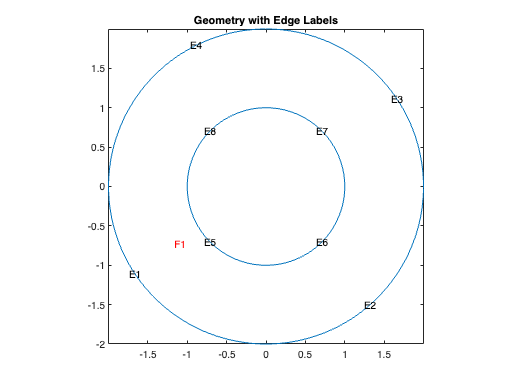

C1 = [1;0;0;2];
C2 = [1;0;0;1];
gd = [C1,C2];
sf = 'C1-C2';
ns = char('C1','C2')';
g = decsg(gd,sf,ns);
pdegplot(g,'EdgeLabels','on','FaceLabels','on') 
xlim([-2.5,2.5])
axis equal
title 'Geometry with Edge Labels';

#### Problem statement

Solve the solution to the following heat equation:


$$\frac{\partial u}{\partial t} -\mathop{div}(c\nabla u) = 0,$$


on the ring $\Omega =\left\lbrace \left(x,y\right)\left|{1\le x}^2 +y^2 \le 2\right.\right\rbrace$, with the Neumann conditions on the boundary $\partial \Omega$. 

- To solve the linear heat equation using the programmatic workflow, first create a PDE model.

numberOfPDE = 1;
model = createpde(numberOfPDE);

         2. Include the geometry in the model.

geometryFromEdges(model,g);

         3. Specify the coefficients.

m = 0; 
d = 1;
c = 1;
a = 0; 
%f = @(location, state) 10*exp((1-location.x.^2 - location.y.^2)/0.01); 
f=0;
specifyCoefficients(model,'m',m,'d',d,'c',c,'a',a,'f',f);

         4. Specify the boundary conditions using the function $u(x,y) = x^2$.

applyBoundaryCondition(model,'neumann', 'Edge',1:model.Geometry.NumEdges,'g',0);

       5. Set the initial  conditions      

sigma = 0.01;
u0 = @(location) exp((1-location.x.^2 - location.y.^2)/sigma);
setInitialConditions(model,u0);

       6. Generate a mesh 

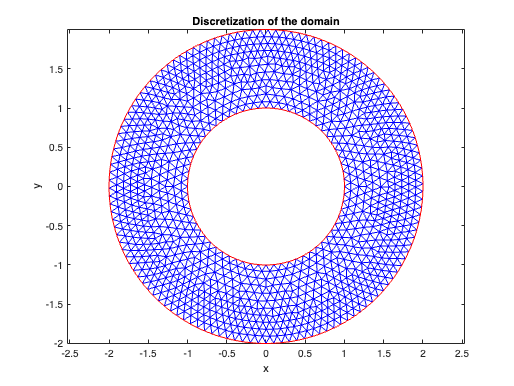

generateMesh(model, 'Hmax',0.1);
figure;
pdemesh(model); 
ylim([-1.1 1.1]); 
axis equal
xlabel x
ylabel y
title 'Discretization of the domain'

       7. Solve the heat equation.

n = 100;
tlist = linspace(0,3,n);
model.SolverOptions.ReportStatistics ='on';
result = solvepde(model,tlist);

145 successful steps
0 failed attempts
292 function evaluations
1 partial derivatives
30 LU decompositions
291 solutions of linear systems


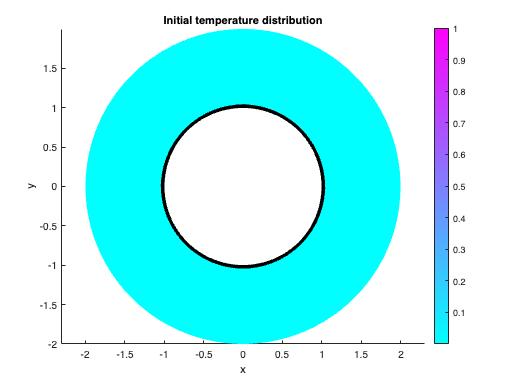

u = result.NodalSolution;
figure;
umax = max(max(u)); umin = min(min(u)); 
pdeplot(model,'XYData',u(:,1),'Contour','on','ColorMap','cool');
axis equal;
xlabel x
ylabel y
title  'Initial temperature distribution'

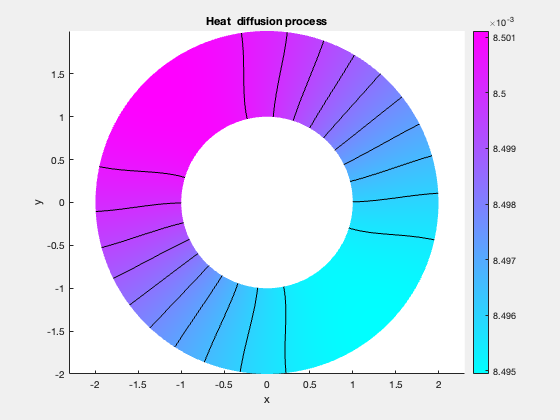

figure;
set(gcf,'Visible','on')
umax = max(max(u)); umin = min(min(u)); 
for i = 1:n
pdeplot(model,'XYData',u(:,i),'Contour','on','ColorMap','cool');
axis equal;
xlabel x
ylabel y
title 'Heat  diffusion process'
M(i) = getframe;
end

Exercise: Try to change c and see how the diffusion process change with respect to the diffussion term c?

Reference: *Partial Differential Equation ToolboxTM User's Guide *